Zerar workspace

clear;

Carregar logs dos sensores

load('logs/wmlog_node1_timetable.mat');
load('logs/wmlog_node2_timetable.mat');
load('logs/wmlog_node4_timetable.mat');

Remoção de dados fora do escopo

% nó 1
wmlog_node1([182:end],:) = [];
wmlog_node1([1:15],:) = [];

% nó 2
wmlog_node2([194:end],:) = [];
wmlog_node2([1:21],:) = [];

% nó 4
wmlog_node4([135:136],:) = [];
wmlog_node4([1:14],:) = [];

Ajustando dados do sensor 03 do nó 1 (multiplicando por -1 para tornar os valores positivos)

wmlog_node1.sensor03value = wmlog_node1.sensor03value * -1;

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizando a formula que leva em consideração a temperatura do solo)

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

wmlog_node1.sensor01cbar = (wmlog_node1.sensor01value-550)./137.5;
wmlog_node1.sensor02cbar = (wmlog_node1.sensor02value-550)./137.5;
wmlog_node1.sensor03cbar = (wmlog_node1.sensor03value-550)./137.5;

wmlog_node2.sensor01cbar = (wmlog_node2.sensor01value-550)./137.5;
wmlog_node2.sensor02cbar = (wmlog_node2.sensor02value-550)./137.5;
wmlog_node2.sensor03cbar = (wmlog_node2.sensor03value-550)./137.5;

wmlog_node4.sensor01cbar = (wmlog_node4.sensor01value-550)./137.5;
wmlog_node4.sensor02cbar = (wmlog_node4.sensor02value-550)./137.5;
wmlog_node4.sensor03cbar = (wmlog_node4.sensor03value-550)./137.5;

Determinar período de tempo a ser utilizado e filtrar tabelas

range = timerange('2017-01-03', '2017-01-05');
node1 = wmlog_node1(range,:);
node2 = wmlog_node2(range,:);
node4 = wmlog_node4(range,:);

TESTE: ajustes de escala

% node4.sensor01cbar = node4.sensor01cbar/100;

Plotar dados dos sensores de 15cm

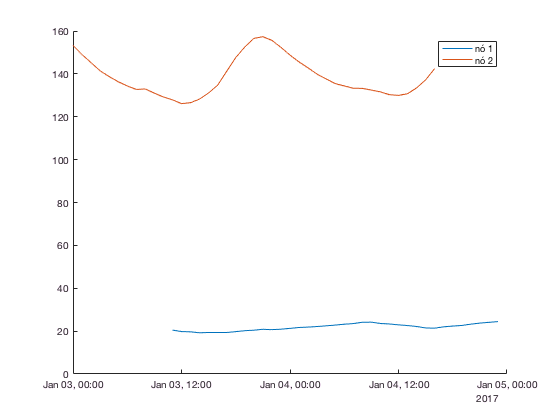

figure
hold on
plot(node1.time,node1.sensor01cbar,'DisplayName','nó 1')
% nó 2
% sensor 1 (15cm) com valores muito altos
plot(node2.time,node2.sensor01cbar,'DisplayName','nó 2')    
% plot(node4.time,node4.sensor01cbar,'DisplayName','nó 4')
hold off
legend('show')

Plotar dados dos sensores de 45cm

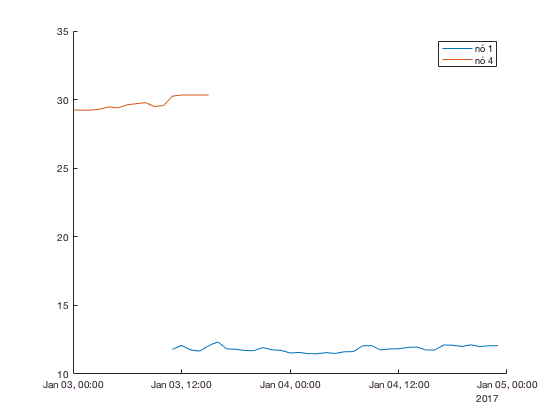

figure
hold on
plot(node1.time,node1.sensor02cbar,'DisplayName','nó 1')
% nó 2
% sensor 2 (45cm) ignorado por ter maioria das leituras nulas (-1 ou -4700)
% plot(node2.time,node2.sensor02cbar,'DisplayName','nó 2')
plot(node4.time,node4.sensor02cbar,'DisplayName','nó 4')
hold off
legend('show')

Plotar dados dos sensores de 75cm

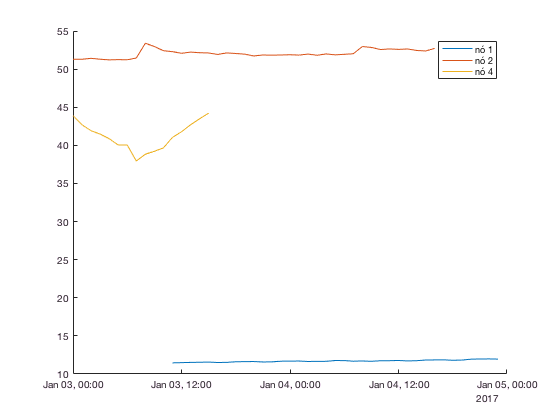

figure
hold on
plot(node1.time,node1.sensor03cbar,'DisplayName','nó 1')
plot(node2.time,node2.sensor03cbar,'DisplayName','nó 2')
% nó 4
% sensor 1 (15cm) com valores muito altos
plot(node4.time,node4.sensor03cbar,'DisplayName','nó 4')
hold off
legend('show')